# Import filtered image and trajectories

imgWL = tiffreadVolume('2_SPTdata/2_SPT_FilteredImage.tif');

df = readtable("2_SPTdata/Tracks.csv");

% Group trajectories by ID
IDs = unique(df.ID);
trajs = cell(length(IDs),1);

for k = 1:length(IDs)
    idx = df.ID == IDs(k);
    trajs{k} = [df.x(idx), df.y(idx)];
end

% Imaging parameters
nFrames = 100;
ExpInfo.scale = 0.094;
ExpInfo.unit = '\mum';
ExpInfo.dt = 18.56; % ms
ExpInfo.dt_unit = 'ms';

## Visualize trajectories

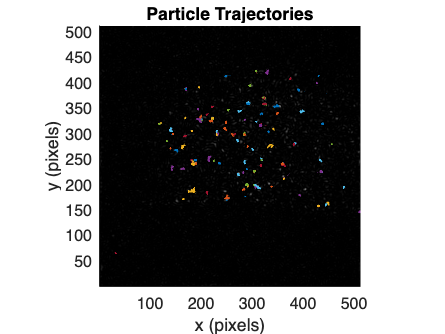

figure; hold on;

imagesc(imgWL(:,:,1)); colormap gray;
axis image;

for k = 1:length(trajs)
    traj = trajs{k};
    plot(traj(:,1), traj(:,2), 'LineWidth', 1);
end

title('Particle Trajectories');
xlabel('x (pixels)');
ylabel('y (pixels)');

## Helper functions

function subtrack = delay_track(track, m)
    N = size(track,1);
    if m < 1 || m >= N
        error('require 1 <= m <= N-1');
    end
    mask = mod(0:N-1, m) == 0;
    subtrack = track(mask,:);
end

function val = MSD_lag(track, m)
    N = size(track,1);
    if m < 1 || m >= N
        error('require 1 <= m <= N-1');
    end

    delayed = delay_track(track, m);
    displ = diff(delayed);

    SD = displ(:,1).^2 + displ(:,2).^2;
    val = mean(SD);
end



function [fig, ax, cbar] = show_cropped_im(im_arr, col_xs, row_ys)
    % Handles incorrect indices (bounds + casting)

    fig = figure;
    ax = axes(fig); 
    hold(ax, 'on');

    n = size(im_arr,1);

    % Ensure integer indices
    col_xs = round(col_xs);
    row_ys = round(row_ys);

    % Clamp to valid bounds
    col_xs(1) = max(col_xs(1), 1);
    col_xs(2) = min(col_xs(2), n);

    row_ys(1) = max(row_ys(1), 1);
    row_ys(2) = min(row_ys(2), n);

    % Crop image
    cropped_im = im_arr(row_ys(1):row_ys(2), col_xs(1):col_xs(2));

    % Display (MATLAB flips y by default differently than matplotlib)
    im = imagesc(ax, ...
        [col_xs(1), col_xs(2)], ...
        [row_ys(2), row_ys(1)], ...
        cropped_im);

    colormap(ax, gray);
    axis(ax, 'image');

    cbar = colorbar(ax);
end


function d = track_dist(track)
    % Compute step distances

    displ = diff(track); % (N-1) x 2

    SD = displ(:,1).^2 + displ(:,2).^2;
    d = sqrt(SD);
end


function pos = px2pos(px_arr, ExpInfo)
    % Convert pixels to physical units
    pos = px_arr * ExpInfo.scale;
end

## MSD functions 

function [t_arr, msd_curve] = MSD_curve_3_noStop(track, ExpInfo, show)
    if nargin < 3
        show = true;
    end

    track_pos = px2pos(track, ExpInfo); 
    N = size(track,1);

    lag_arr = (1:N-1)';
    msd_curve = zeros(N-1,1);

    for m = lag_arr'
        msd_curve(m) = MSD_lag(track_pos, m);
    end

    t_arr = lag_arr * ExpInfo.dt * 1e-3;

    if show
        figure;
        plot(t_arr, msd_curve, 'k', 'LineWidth', 1);
        xlabel('Lag time [s]');
        ylabel(['MSD [' ExpInfo.unit '^2]']);
    end
end

function [D, R2] = MSD_curve_ij_noStop(track, ExpInfo, i, j, show)

    if nargin < 5
        show = true;
    end

    track_pos = px2pos(track, ExpInfo);

    lag_arr = (i:j)';
    n_pts = length(lag_arr);
    msd_curve = zeros(n_pts,1);

    for idx = 1:n_pts
        m = lag_arr(idx);
        msd_curve(idx) = MSD_lag(track_pos, m);
    end

    t_arr = lag_arr * ExpInfo.dt * 1e-3;

    % Linear fit through origin 
    a = (t_arr \ msd_curve);  % least squares slope

    yfit = a * t_arr;

    % R²
    SSres = sum((msd_curve - yfit).^2);
    SStot = sum((msd_curve - mean(msd_curve)).^2);
    R2 = 1 - SSres/SStot;

    D = a / 4;

    if show
        scatter(t_arr, msd_curve, '.'); hold on;
        plot(t_arr, yfit, '--');
        xlabel(['Lag time [' ExpInfo.dt_unit ']']);
        ylabel(['MSD [' ExpInfo.unit '^2]']);
    end
end

## View example trajectory

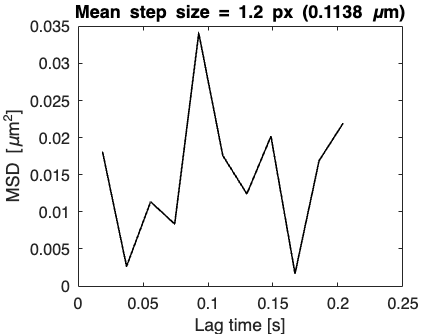

trajToView = 2;
track = trajs{trajToView};

[t, msd] = MSD_curve_3_noStop(track, ExpInfo, true);

avg_step = mean(sqrt(sum(diff(track).^2,2)));

title(['Mean step size = ' num2str(avg_step,2) ' px (' ...
       num2str(avg_step*ExpInfo.scale,4) ' ' ExpInfo.unit ')']);


[D, R2] = MSD_curve_ij_noStop(track, ExpInfo, 1, length(track)-1, false);


## Loop over trajectories

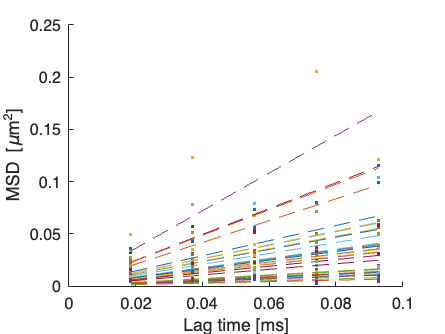

%% Loop through all trajectories

% Filter long trajectories
trajs_long = trajs(cellfun(@(x) size(x,1) > 15, trajs));

D = zeros(length(trajs_long),1);
R2 = zeros(length(trajs_long),1);

figure; hold on;

for tj = 1:length(trajs_long)

    track = trajs_long{tj};

    [t, msd] = MSD_curve_3_noStop(track, ExpInfo, false);

    % only fit early points
    jmax = min(5, length(track)-1);

    [D(tj), R2(tj)] = MSD_curve_ij_noStop(track, ExpInfo, 1, jmax, true);

end